# Markov Model: Finding an Equilibrium of State Probabilities

clear;clc;clf

We'll begin by reviewing how we define a trnsition matrix for a markov model that describes successinon dynamics for each patch of land.  

Let $P(X_t=1)$, $P(X_t=2 )$, and $P(X_t=3 )$ represent the probabilities that the patch of land is dominated by each of the three states at time $t$. Increment time forward from $t$ by a discrete step to $t + 1$. Predict $P(X_{t+1}=1)$, $P(X_{t+1}=2)$, and $P(X_{t+1}=3)$ (the probabilities that the patch of land will be dominated by each of three states at time $t + 1$) given knowledge of the same probabilities at time $t$.

Do so by invoking the law of total probability:


$$P(X_{t+1}=1) = P(X_{t+1}=1 | X_t=1)P(X_t=1) + P(X_{t+1}=1 | X_t=2)P(X_t=2) + P(X_{t+1}=1 | X_t=3)P(X_t=3)$$



$$P(X_{t+1}=2) = P(X_{t+1}=2 | X_t=1)P(X_t=1) + P(X_{t+1}=2 | X_t=2)P(X_t=2) + P(X_{t+1}=2 | X_t=3)P(X_t=3)$$



$$P(X_{t+1}=3) = P(X_{t+1}=3 | X_t=1)P(X_t=1) + P(X_{t+1}=3 | X_t=2)P(X_t=2) + P(X_{t+1}=3 | X_t=3)P(X_t=3)$$


This may be written as a matrix equation.

$\left(\begin{array}{c}P(X_{t+1}=1)\\P(X_{t+1}=2)\\P(X_{t+1}=3)\end{array}\right)=\left(\begin{array}{ccc}P(X_{t+1}=1 | X_t=1) & P(X_{t+1}=1 | X_t=2) & P(X_{t+1}=1 | X_t=3)\\
P(X_{t+1}=2 | X_t=1) & P(X_{t+1}=2 | X_t=2) & P(X_{t+1}=2 | X_t=3)\\
P(X_{t+1}=3 | X_t=1) & P(X_{t+1}=3 | X_t=2) & P(X_{t+1}=3 | X_t=3) \end{array}\right)\cdot\left(\begin{array}{c}P(X_{t}=1)\\P(X_{t}=2)\\P(X_{t}=3) \end{array} \right)$The matrix in this equation is the transition matrix. Its columns are probabilities that must sum to 1. For instance, valid values might be

M=[
    0.70 0.25 0.11;
    0.14 0.63 0.04;
    0.16 0.12 0.85
    ]

M =     0.7000    0.2500    0.1100
    0.1400    0.6300    0.0400
    0.1600    0.1200    0.8500


We can simulate the vegetation dominance in a single plot of land as a time series as modeled by a discrete time Markov model.  In this approach, we randomly initialize the dominant state to one of the three possibilities: Shrubs (1), Grasses (2) or Bare Ground (3). Then the current state dictates which column of the transition matrix we use as a distribution to sample from.  We use randsample to make a single choice of the values 1, 2, or 3 distributed according to the weights in the column.

steps=45;       % number of steps in time series
n=3;            % number of states
ts=randi(n);    %random initial state


% simulate a time series of observed Markov states at each of the sites.
% Each row of the ts matrix will represent one of these time series
for i=1:steps
    ts=[ts;randsample(n,1,true,M(:,ts(end)))];
end

This gives us a time series of dominant states at the plot of land.  We may visualize them over time.

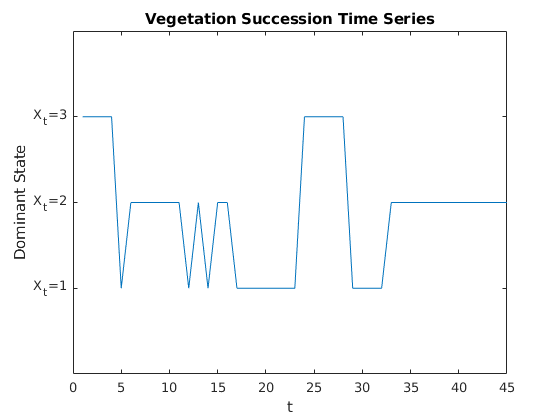

%visualize 
figure(1)
plot(ts)
title('Vegetation Succession Time Series')
xlabel('t')
ylabel('Dominant State')
yticks([1,2,3])
yticklabels({'X_t=1','X_t=2','X_t=3'})
ylim([0,4])
xlim([0,45])